### Fig 9

r = 1;         
a = 0.09;          
Omega = 50;   
alpha = 2;
delta = 0.04;  
f = 0.02;
K0 = 1;


B0 = 0.1;
I0 = 0.1;
P0 = 10;


tspan_total = [0 5000]; 
t_burn = 3000;            


A_vec = 0:0.002:1;

bif_data = [];

% ODE
options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);


y0 = [B0; I0; P0];


for i = 1:length(A_vec)
    A = A_vec(i);
    fprintf('Running simulation for A = %.3f (%d/%d)\n', A, i, length(A_vec));
    

    [t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, A, f, r, K0, a, Omega, alpha, delta), tspan_total, y0, options);

    idx_steady = t > t_burn;
    t_steady = t(idx_steady);
    B_steady = y(idx_steady, 1) * 1e8;  
    I_steady = y(idx_steady, 2) * 1e8;
    P_steady = y(idx_steady, 3) * 1e8;
    
    %Calculate the average value during the steady-state phase to use as the initial condition for the next iteration.
    if ~isempty(B_steady)
        B0_next = mean(y(idx_steady, 1));
        I0_next = mean(y(idx_steady, 2));
        P0_next = mean(y(idx_steady, 3));
        y0 = [B0_next; I0_next; P0_next];
    else
        fprintf('Warning: No steady state data for A = %.3f\n', A);
    end
    

    if length(B_steady) < 3
        continue;
    end
    
    [troughs, ~] = findpeaks(-B_steady);    
    troughs = -troughs; 
  
    if ~isempty(troughs)
        for j = 1:length(troughs)
            bif_data(end+1, :) = [A, troughs(j)];
        end
    else
        bif_data(end+1, :) = [A, NaN]; 
    end
end

Running simulation for A = 0.000 (1/501)
Running simulation for A = 0.002 (2/501)
Running simulation for A = 0.004 (3/501)
Running simulation for A = 0.006 (4/501)
Running simulation for A = 0.008 (5/501)
Running simulation for A = 0.010 (6/501)
Running simulation for A = 0.012 (7/501)
Running simulation for A = 0.014 (8/501)
Running simulation for A = 0.016 (9/501)
Running simulation for A = 0.018 (10/501)
Running simulation for A = 0.020 (11/501)
Running simulation for A = 0.022 (12/501)
Running simulation for A = 0.024 (13/501)
Running simulation for A = 0.026 (14/501)
Running simulation for A = 0.028 (15/501)
Running simulation for A = 0.030 (16/501)
Running simulation for A = 0.032 (17/501)
Running simulation for A = 0.034 (18/501)
Running simulation for A = 0.036 (19/501)
Running simulation for A = 0.038 (20/501)
Running simulation for A = 0.040 (21/501)
Running simulation for A = 0.042 (22/501)
Running simulation for A = 0.044 (23/501)
Running simulation for A = 0.046 (24/501)
R

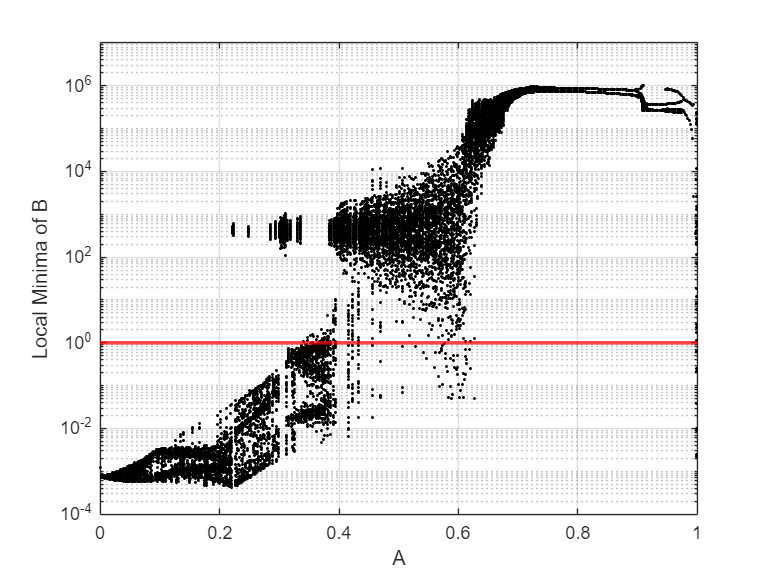

%Visualization
figure;
hold on;
plot(bif_data(:,1), bif_data(:,2), 'k.', 'MarkerSize', 5);
set(gca,'Yscale','log');
xlabel('A');
ylabel('Local Minima of B');
xlim([min(A_vec), 1]);
ylim([10^-4,10^7]);
yline(1, 'r-', 'LineWidth', 2, 'Color', 'red');
grid on;
box on;
hold off;


clear;
r = 1;          
a = 0.09;     
Omega = 50;     
alpha = 2;
delta = 0.04;   
A = 0.2;       
K0 = 1;


B0 = 0.1;
I0 = 0.1;
P0 = 10;

y0 = [B0; I0; P0];

tspan_total = [0 5000];   
t_burn = 3000;            




bif_data = [];

% ODE
options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
[t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, 0, 0, r, K0, a, Omega, alpha, delta), tspan_total, y0, options);
f0=PSD_max(y, t,tspan_total(2));

f_vec = logspace(log10(f0/1.5),log10(f0*5),500); 



for i = 1:length(f_vec)
    f = f_vec(i);
    fprintf('Running simulation for f = %.5f (%d/%d)\n', f, i, length(f_vec));
    

    [t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, A, f, r, K0, a, Omega, alpha, delta), tspan_total, y0, options);
    

    idx_steady = t > t_burn;
    t_steady = t(idx_steady);
    B_steady = y(idx_steady, 1) * 1e8;
    

    if length(B_steady) < 3
        continue;
    end
    

    [troughs, ~] = findpeaks(-B_steady); 
    troughs = -troughs;
    

    if ~isempty(troughs)
        for j = 1:length(troughs)
            bif_data(end+1, :) = [f, troughs(j)];
        end
    else
        bif_data(end+1, :) = [f, NaN];
    end
end

Running simulation for f = 0.00886 (1/500)
Running simulation for f = 0.00889 (2/500)
Running simulation for f = 0.00893 (3/500)
Running simulation for f = 0.00896 (4/500)
Running simulation for f = 0.00900 (5/500)
Running simulation for f = 0.00904 (6/500)
Running simulation for f = 0.00907 (7/500)
Running simulation for f = 0.00911 (8/500)
Running simulation for f = 0.00915 (9/500)
Running simulation for f = 0.00918 (10/500)
Running simulation for f = 0.00922 (11/500)
Running simulation for f = 0.00926 (12/500)
Running simulation for f = 0.00930 (13/500)
Running simulation for f = 0.00933 (14/500)
Running simulation for f = 0.00937 (15/500)
Running simulation for f = 0.00941 (16/500)
Running simulation for f = 0.00945 (17/500)
Running simulation for f = 0.00949 (18/500)
Running simulation for f = 0.00952 (19/500)
Running simulation for f = 0.00956 (20/500)
Running simulation for f = 0.00960 (21/500)
Running simulation for f = 0.00964 (22/500)
Running simulation for f = 0.00968 (23/50

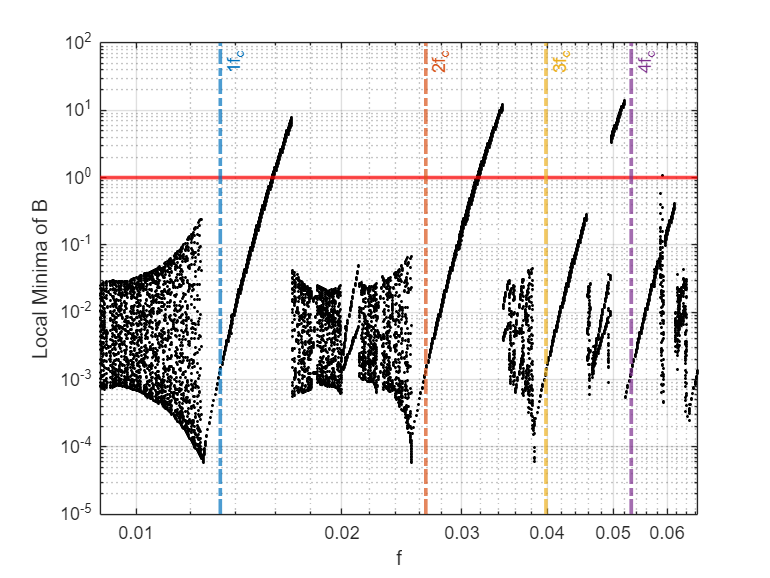

%Visualization
figure;
hold on;


plot(bif_data(:,1), bif_data(:,2), 'k.', 'MarkerSize', 5);


set(gca, 'YScale', 'log', 'XScale', 'log');
xlabel('f');
ylabel('Local Minima of B');
xlim([min(f_vec), max(f_vec)]);
grid on;

n_list = [1, 2, 3, 4];
colors = lines(5);

yline(1, 'r-', 'LineWidth', 2, 'Color', 'red');
for n = n_list
    x2 = n * f0;
    if x2 >= min(f_vec) && x2 <= max(f_vec)
        xline(x2, '-.', sprintf('%df_c', n), 'Color', colors(n,:), 'LineWidth', 2);
    end
end
box on;
hold off;


clear;
r = 1;          
a = 0.09;       
Omega = 50;     
alpha = 2;
delta = 0.04;   
K0 = 1;


B0 = 0.1;
I0 = 0.1;
P0 = 10;
y0 = [B0; I0; P0];


tspan_total = [0 5000];   
t_burn = 3000;            

% ODE

options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
[t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, 0, 0, r, K0, a, Omega, alpha, delta), tspan_total, y0, options);
f0=PSD_max(y, t,tspan_total(2));

A_vec = 0:0.01:1; 
f_vec = logspace(log10(f0/1.5), log10(f0*5), 100); 


minB_matrix = zeros(length(A_vec), length(f_vec));


for i = 1:length(A_vec)
    A = A_vec(i);
    fprintf('Running simulations for A = %.4f (%d/%d)\n', A, i, length(A_vec));
    
    parfor j = 1:length(f_vec)
        f = f_vec(j);
        

        [t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, A, f, r, K0, a, Omega, alpha, delta), ...
                        tspan_total, y0, options);
        

        idx_steady = t > t_burn;
        B_steady = y(idx_steady, 1)*10^8;
        

        if ~isempty(B_steady) && all(isfinite(B_steady))
            minB_matrix(i, j) = min(B_steady);
        else
            minB_matrix(i, j) = NaN;
        end
    end
end

Running simulations for A = 0.0000 (1/101)


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


Running simulations for A = 0.0100 (2/101)
Running simulations for A = 0.0200 (3/101)
Running simulations for A = 0.0300 (4/101)
Running simulations for A = 0.0400 (5/101)
Running simulations for A = 0.0500 (6/101)
Running simulations for A = 0.0600 (7/101)
Running simulations for A = 0.0700 (8/101)
Running simulations for A = 0.0800 (9/101)
Running simulations for A = 0.0900 (10/101)
Running simulations for A = 0.1000 (11/101)
Running simulations for A = 0.1100 (12/101)
Running simulations for A = 0.1200 (13/101)
Running simulations for A = 0.1300 (14/101)
Running simulations for A = 0.1400 (15/101)
Running simulations for A = 0.1500 (16/101)
Running simulations for A = 0.1600 (17/101)
Running simulations for A = 0.1700 (18/101)
Running simulations for A = 0.1800 (19/101)
Running simulations for A = 0.1900 (20/101)
Running simulations for A = 0.2000 (21/101)
Running simulations for A = 0.2100 (22/101)
Running simulations for A = 0.2200 (23/101)
Running simulations for A = 0.2300 (24/1

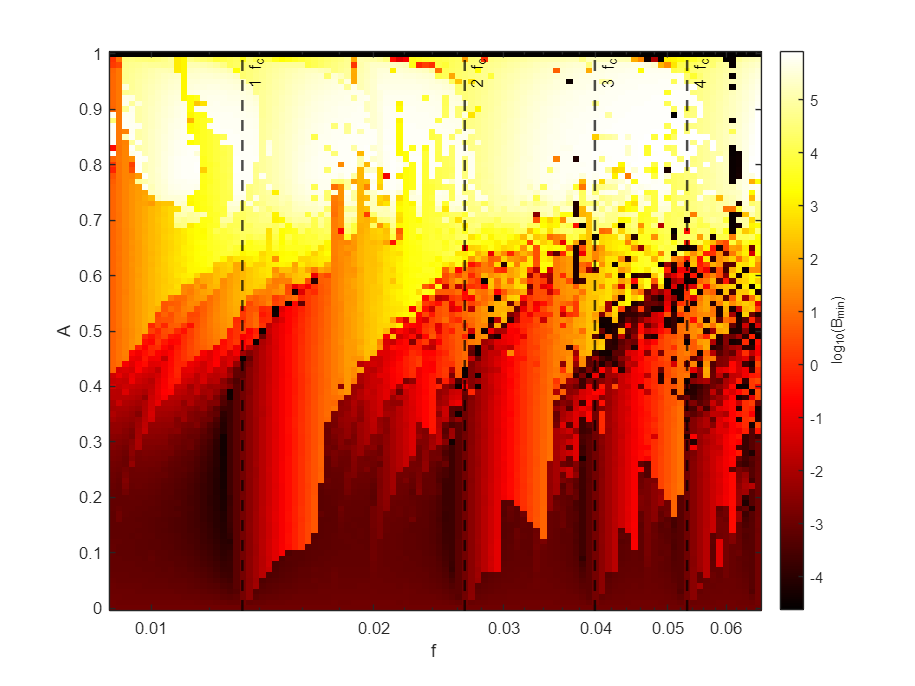

% Visualization
figure;
set(gcf, 'Position', [100, 100, 800, 600]);
imagesc(f_vec, A_vec, log10(minB_matrix));
colormap hot;
axis xy;  
colorbar;
hcb = colorbar;
hcb.Label.String = 'log_{10}(B_{min})';
xlabel('f');
ylabel('A');
set(gca, 'XScale', 'log');  
ylabel('A');
xlabel('f ');

hold on;
n_list = [1, 2, 3, 4];
colors = lines(4);
for n = n_list
    f_n = n * f0;
    if f_n >= min(f_vec) && f_n <= max(f_vec)
        xline(f_n, 'k--', sprintf('%d f_c', n), 'LineWidth', 1.5);
    end
end
box on;
axis tight;
hold off;